# Check array response function (ARF) and grid resolution

Katrin Löer [k.loer@tudelft.nl](mailto:k.loer@tudelft.nl) Apr 2023 

last modified: Feb 2024 (improved figures)

%%-------------------------------------------------------------------------

close all
clear

## Please specify:

% Add paths to plotting functions and colourmaps
addpath('/Users/kloer/Documents/MATLAB/crameri');

save_figs = false;

## PROCESSING PARAMETERS (don't change)

% Load set of parameters
b3am_param;
addpath(plotfolder);
addpath(beamfolder)

figpath = './Figures';
if exist(figpath,'dir')==0
    [SUCCESS,MESSAGE,MESSAGEID] = mkdir(figpath);
end

% Compute wavenumber range from station spacing
%----------------------------------------------

fid = fopen(stationfile,'r');
S = textscan(fid, '%s %f %f', 'Headerlines', nheader);
snames = S{1};
nstat = length(snames);
fprintf('Number of stations: %d\n\n',nstat);

Number of stations: 34




coords_txt = zeros(nstat,2);
coords_txt(:,1) = S{2};
coords_txt(:,2) = S{3};
clear S

[mindist, maxdist, imin, jmin, imax, jmax] = f_compminmaxdist(coords_txt);
% Note: theoretical coordinate information is used to define the wavenumber
% range. In the beamformer, coordinates of actually available stations
% need to be used (from DAT.h.coords)

fprintf('Maximum station spacing: dmax = %.0f m\n',maxdist);

Maximum station spacing: dmax = 13322 m


fprintf('Minimum station spacing: dmin = %.0f m\n\n',mindist);

Minimum station spacing: dmin = 741 m




% Wavenumber grid
if exist('kmax','var')==0   
    kmax = 1/(2*mindist);
end
if exist('kmin','var')==0  
    kmin = 1/(3*maxdist);
end
if exist('kres','var')==0
    kres = 201;
end

kgrid = linspace(0,kmax,kres)';

% Wavelengths
lmin = 1/kmax;
lmax = 1/kmin;

fprintf('Maximum wavelength: lmax = %.0f m\n',lmax);

Maximum wavelength: lmax = 20000 m


fprintf('Minimum wavelength: lmin = %.0f m\n\n',lmin);

Minimum wavelength: lmin = 1000 m




fprintf('Maximum wavenumber: kmax = %.3f 1/km\n',kmax*1000);

Maximum wavenumber: kmax = 1.000 1/km


fprintf('Minimum wavenumber (resolution limit): kmin = %.3f 1/km\n',kmin*1000);

Minimum wavenumber (resolution limit): kmin = 0.050 1/km


fprintf('Wavenumber step size for %d grid points: dk = %.3f 1/km\n\n',kres,kgrid(2)*1000);

Wavenumber step size for 201 grid points: dk = 0.005 1/km



## More processing parameters

%---------------------------

% Azimuth grid
if exist('ares','var')==0
    astep = 5;
end
procpars.agrid = -(180-astep):astep:180;

% Dig grid
if exist('dres','var')==0
    dres = 10;
end
procpars.dgrid = 0:dres:90;

% Ellipticity grid
if exist('emin','var')==0 && exist('emax','var')==0
    emin = 0.1;
    emax = 1.9;
end
if exist('eres','var')==0
    eres = 0.1;
end
procpars.egrid = emin:eres:emax;

## Plot ARF

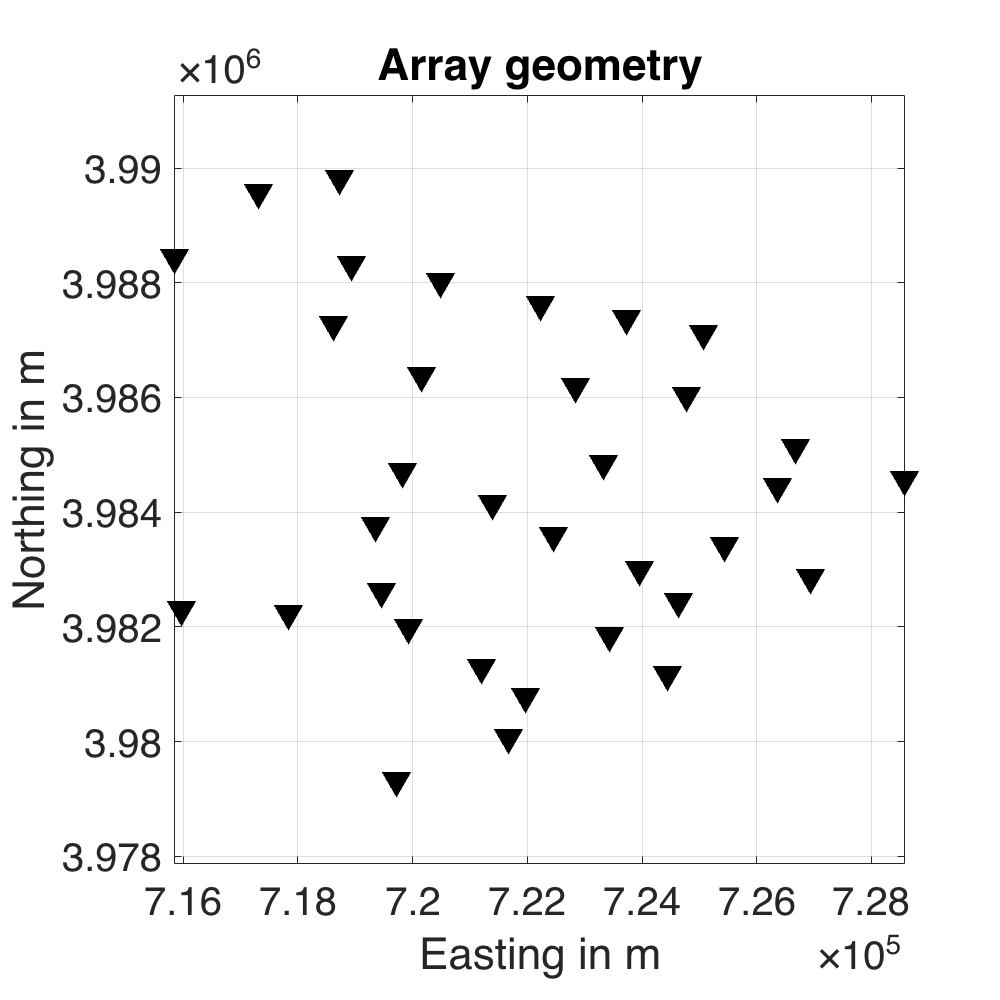

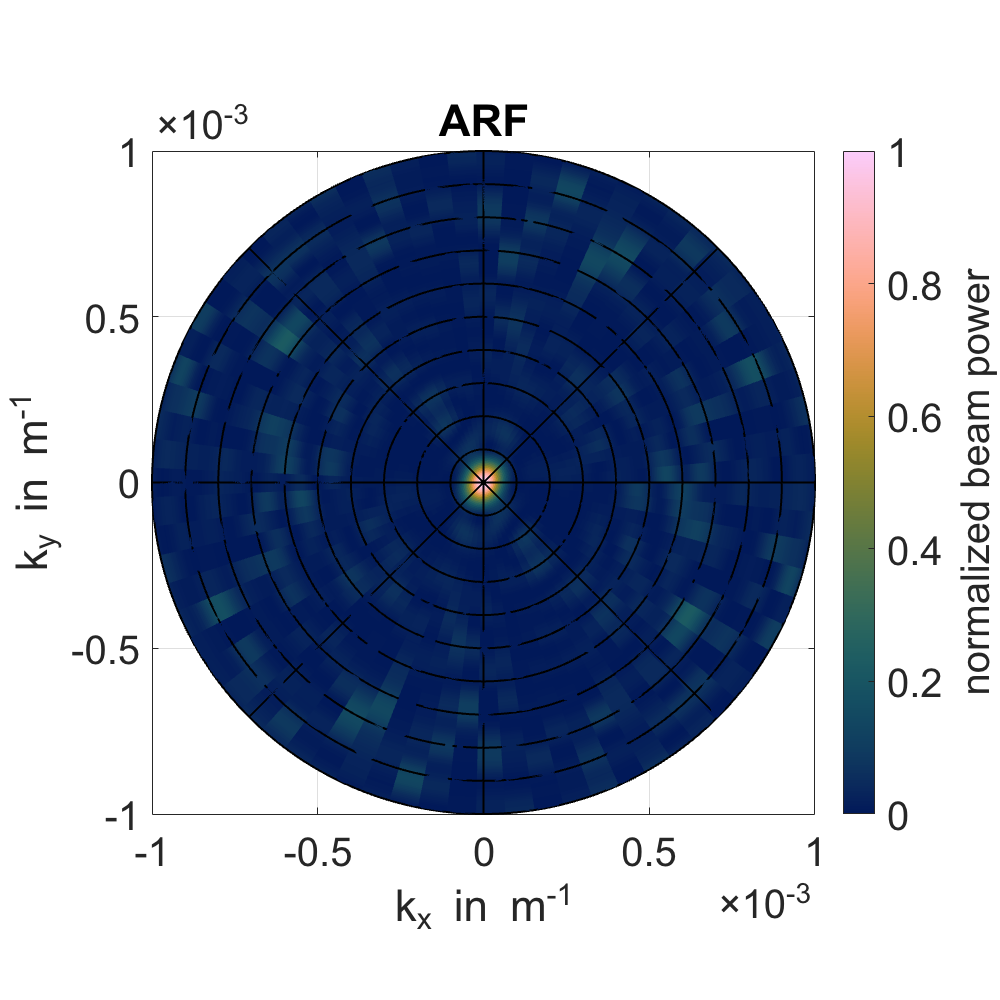

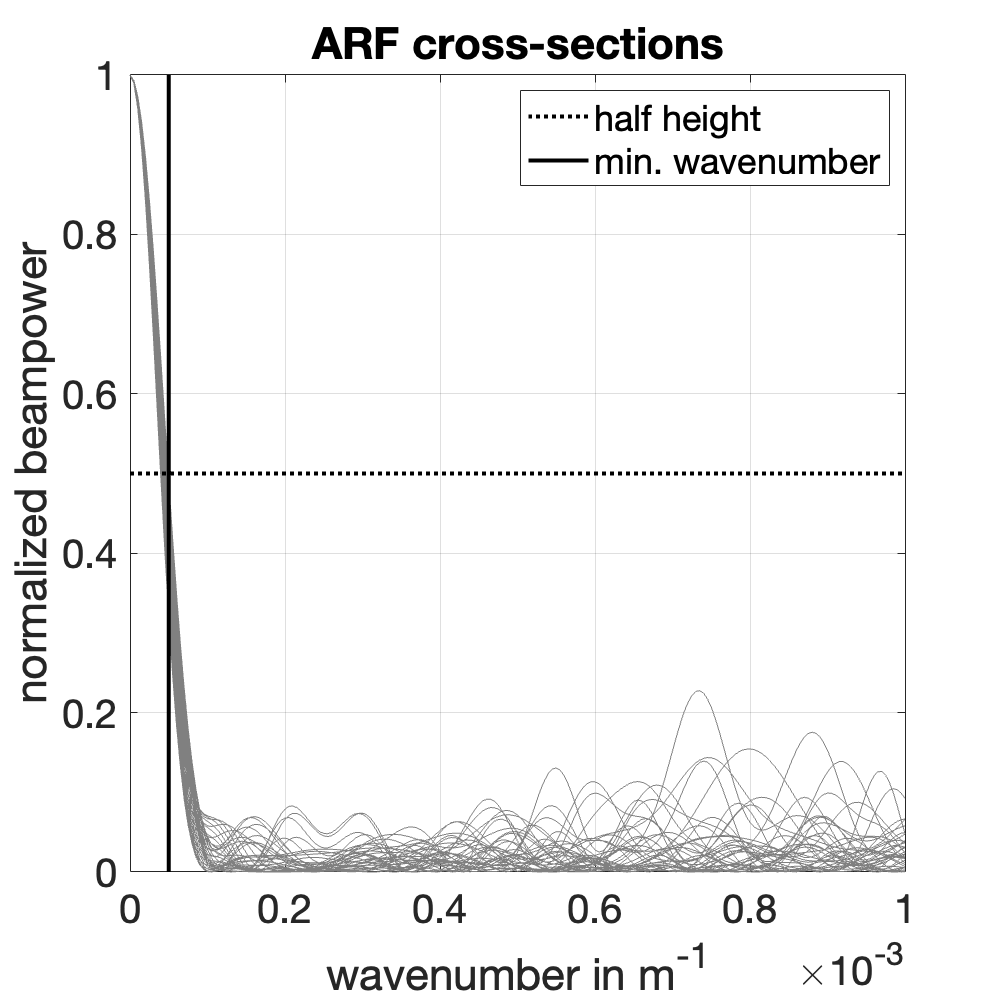

%-----------
% Plot array geometry, array response function (ARF), and cross sections of 
% ARF to check wavenumber limits
% 
% Wathelet et al. (2008) recommend a maximum wavenumber above kmin for which A < 0.5 Amax

f_plotarf(coords_txt,kmin,kmax,kres,astep,'norm',save_figs,figpath)

## Frequency-dependent velocity grids

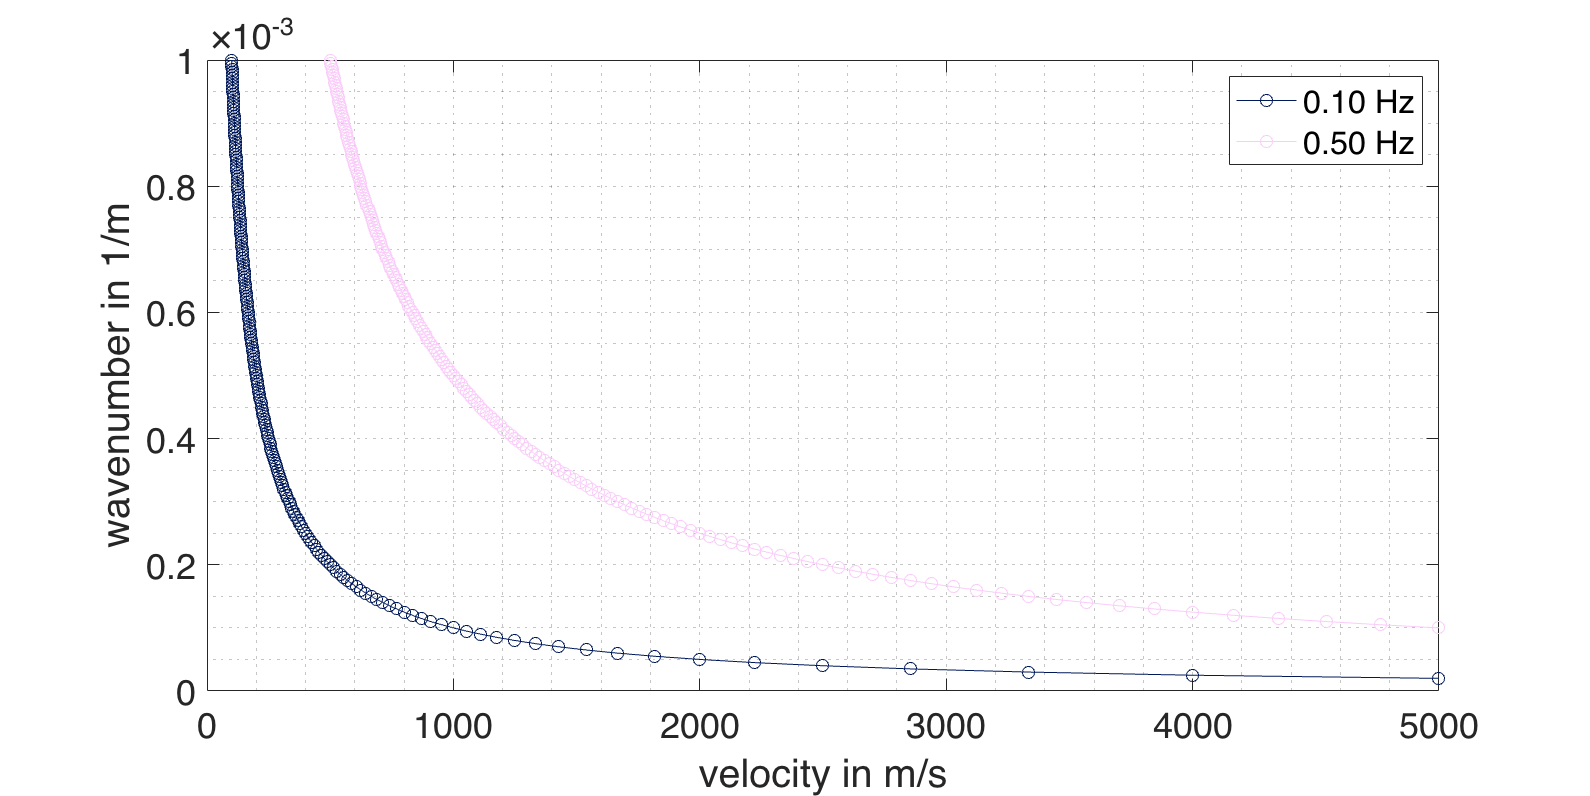

%------------------------------------

figure('Color','white','Position',[100 100 1000 500]); 
load batlowS
hold on
plot(fmin./kgrid,kgrid,'-o','Color',batlowS(1,:))
plot(fmax./kgrid,kgrid,'-o','Color',batlowS(2,:))
xlim([0 5000])
ylim([0 kmax])
box on
grid minor
xlabel('velocity in m/s')
ylabel('wavenumber in 1/m')
set(gca,'Fontsize',18);

legend(sprintf('%.2f Hz',fmin),sprintf('%.2f Hz',fmax))


% Chosen frequencies
fprintf('Maximum frequency: fmax = %.2f Hz\n',fmax);

Maximum frequency: fmax = 0.50 Hz


fprintf('Minimum frequency: fmin = %.2f Hz\n\n',fmin);

Minimum frequency: fmin = 0.10 Hz




% Velocities
vmin = fmax/kmax;
fprintf('Minimum velocity at %.2f Hz: vmax = %4.0f m/s\n',fmax,vmin);

Minimum velocity at 0.50 Hz: vmax =  500 m/s



if save_figs
    figname = [figpath, '/04_velocities.png'];
    print(figname,'-dpng')
end

## EOF